# Part 1: Lena.tif

% Read and load the images for lena
% (a) image resize?
lena = imread("Lena-3.tif");
% lena has 256x256 pixels -> split into 2 images
lena_1 = lena(1:512, 1:256, :);
lena_2 = lena(1:512, 257:512, :);

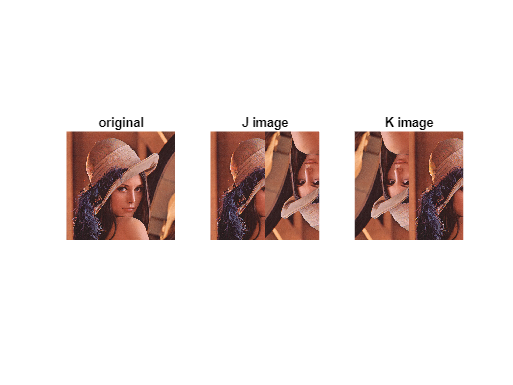

% (b) swapping left and right halves of the photo the merge the photo
lena_2_rot = imrotate(lena_2, 180);
lena_cat = cat(2, lena_1, lena_2_rot);
lena_rot = cat(2, lena_2_rot, lena_1);
% Plot images
figure;
subplot(131);
imshow(lena);
title('original');
subplot(132);
imshow(lena_cat);
title('J image');
subplot(133);
imshow(lena_rot);
title('K image');

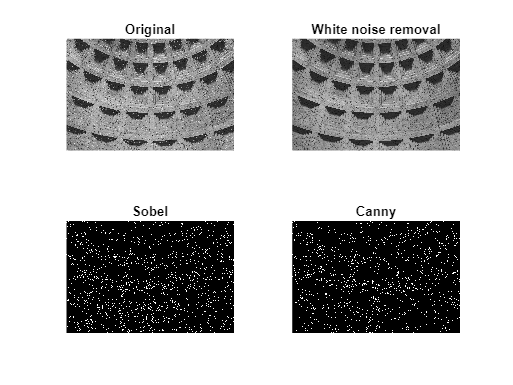

% (c) detect edges kranen1.tif and notredam2.tif - Canny and Sobel edge detection
kranen1 = imread('kranen1.tif');
notre = imread('notredam2.tif');
% grayscale images
kranen_gs = rgb2gray(kranen1);
notre_gs = rgb2gray(notre);
% kranen image preprocessing (white noise removal)
kranen_filter = strel('disk', 2);
kranen_fil = imopen(kranen_gs, kranen_filter);
% notre_fil = imclose(notre_gs, kranen_fil);
% Sobel method
kranen_s = edge(kranen_fil, "sobel");
notre_s = edge(notre_gs, "sobel");
% Canny method
kranen_c = edge(kranen_fil, "canny", 0.37, 1);
notre_c = edge(notre_gs, "canny", 0.2, 1);
% Plot images and edges for kranen image
figure;
subplot(221); imshow(kranen_gs); title('Original');
subplot(222); imshow(kranen_fil); title('White noise removal');
subplot(223); imshow(kranen_s); title('Sobel');
subplot(224); imshow(kranen_c); title('Canny');

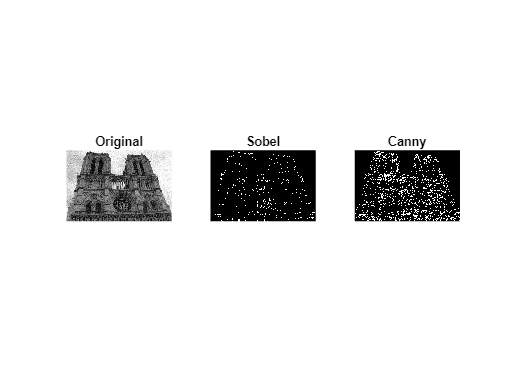

% Plot images and edge for notre image
figure;
subplot(131); imshow(notre_gs); title('Original');
subplot(132); imshow(notre_s); title('Sobel');
subplot(133); imshow(notre_c); title('Canny');

## Part 2: Image Restoration/Transformation

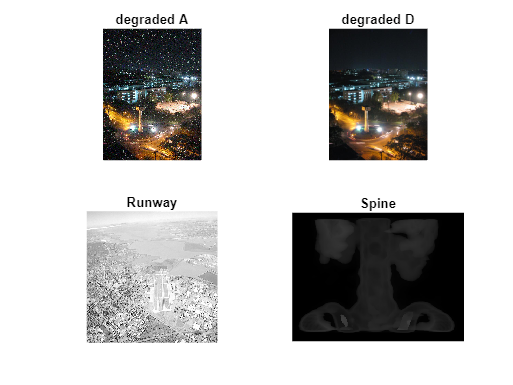

% read the images
degraded_a = imread("Degraded_A.tif");
degraded_d = imread("Degraded_D..tif");
runway = imread("runway-1.tif");
spine = imread("spine.tif");

% Plot the images and assess the problems
figure;
subplot(221); imshow(degraded_a); title('degraded A');
subplot(222); imshow(degraded_d); title('degraded D');
subplot(223); imshow(runway); title('Runway');
subplot(224); imshow(spine); title('Spine');